clear

mu_h=67;sig_h=2;
mu_w=150;sig_w=4;
rho=0.75;
S=[sig_h*sig_h rho*sig_h*sig_w;
   rho*sig_h*sig_w sig_w*sig_w];

A=chol(S)';

m=10e6;

U1=rand(m,1);
U2=rand(m,1);

Z1A=sqrt(-2.*log(U1)).*cos(2*pi.*U2);
Z2A=sqrt(-2.*log(U1)).*sin(2*pi.*U2);

X1 = A(1,1)*Z1A+mu_h;
X2 = A(2,1)*Z1A+A(2,2)*Z2A+mu_w;

%10^6 2*1 verctor
X=[X1';X2'] 

X =    68.4859   66.0060   68.8316   66.7393   66.7773   65.9752   64.5947   68.1753   67.0425   64.5964   66.8162   67.6032   68.3877   67.2070   71.9871   66.1754   67.2235   63.8594   68.9979   69.5488   64.3888   62.6841   64.1041   63.7881   64.2438   68.3704   67.5431   67.5688   70.0158   67.0585   71.2968   66.7343   67.6269   65.6898   67.7974   67.4947   66.7128   67.8841   66.0956   67.3083   65.9528   68.0318   71.0535   65.3522   66.8264   66.0119   66.0891   65.1170   64.8142   72.6220
  149.0069  145.1665  152.8838  152.8443  152.1341  150.0478  144.6087  152.3621  149.5152  147.1624  146.3732  149.9920  154.2061  148.9762  154.2702  144.9001  147.8143  145.0678  154.1823  154.5770  142.8717  144.9837  144.4762  148.5055  147.7665  158.7951  146.4547  152.6524  154.8674  151.1400  152.7803  155.0236  153.1598  147.1057  149.1316  152.5368  148.3767  152.1284  148.6623  154.7661  150.5897  150.8179  158.0442  148.3015  146.9042  144.7794  151.7806  150.9134  145.1066  156


%divide to samples of 10
Xk=permute(reshape(X, 2, 10, m/10), [1, 2, 3])

Xk = Xk(:,:,1) =

   68.4859   66.0060   68.8316   66.7393   66.7773   65.9752   64.5947   68.1753   67.0425   64.5964
  149.0069  145.1665  152.8838  152.8443  152.1341  150.0478  144.6087  152.3621  149.5152  147.1624


Xk(:,:,2) =

   66.8162   67.6032   68.3877   67.2070   71.9871   66.1754   67.2235   63.8594   68.9979   69.5488
  146.3732  149.9920  154.2061  148.9762  154.2702  144.9001  147.8143  145.0678  154.1823  154.5770


Xk(:,:,3) =

   64.3888   62.6841   64.1041   63.7881   64.2438   68.3704   67.5431   67.5688   70.0158   67.0585
  142.8717  144.9837  144.4762  148.5055  147.7665  158.7951  146.4547  152.6524  154.8674  151.1400


Xk(:,:,4) =

   71.2968   66.7343   67.6269   65.6898   67.7974   67.4947   66.7128   67.8841   66.0956   67.3083
  152.7803  155.0236  153.1598  147.1057  149.1316  152.5368  148.3767  152.1284  148.6623  154.7661


Xk(:,:,5) =

   65.9528   68.0318   71.0535   65.3522   66.8264   66.0119   66.0891   65.1170   64.8142   72.6220
  150.5897  1


%mean,var,cov of each 10
Mean_Xw_h=reshape(mean(Xk(1,:,:)),m/10,1)';
Mean_Xw_w=reshape(mean(Xk(2,:,:)),m/10,1)';
Mean_Xk=[Mean_Xw_h;Mean_Xw_w]

Mean_Xk =    66.7224   67.7806   65.9765   67.4641   67.1871   67.0655   66.5050   66.7374   66.5965   66.1160   66.7971   65.7666   67.0154   66.5890   67.2769   66.4380   67.9748   67.5173   67.1775   66.5219   65.5988   67.1659   67.4716   66.0537   66.9712   67.2236   65.5486   67.6526   67.2595   66.7739   67.9313   66.9208   67.2711   67.7960   67.1251   67.3909   68.2210   66.9954   66.0158   66.8714   66.7959   66.5335   67.6120   67.9129   67.2192   67.1222   66.8623   68.0011   66.3012   66.9142
  149.5732  150.0359  149.2513  151.3671  150.4004  149.6002  149.4833  149.6968  149.4098  148.7786  148.1853  147.4459  149.2751  148.9842  149.6961  149.8803  150.8854  151.7539  149.5742  148.7390  147.8760  149.7840  151.1667  148.1492  150.9216  150.2355  148.2658  152.2200  150.2535  149.5063  150.8082  151.1835  151.0539  151.7023  149.0624  151.3891  152.2416  150.4981  147.5710  150.0756  151.6279  149.7966  151.2470  152.0771  150.3420  151.1439  150.2194  151.5674  150.244


Var_h=reshape(var(Xk(1,:,:)),m/10,1)';
Var_w=reshape(var(Xk(2,:,:)),m/10,1)';
Var_Xk=[Var_h;Var_w]

Var_Xk =     2.2104    4.6917    5.8739    2.3496    6.9694    2.9056    4.5043    3.0306    6.2034    2.1719    1.9325    3.5428    1.8797    5.7608    5.4371    3.2483    3.5337    3.4411    3.3316    4.2951    3.2277    2.6488    3.0352    1.1038    4.6250    5.5254    4.1458    1.2953    5.0076    4.6885    3.0015    4.4719    5.6290    3.1339    1.8389    5.0907    2.6445    4.6658    6.3212    3.1201    1.5246    3.7530    7.2306    6.2468    6.6844    2.3853    2.2082   11.0705    4.0120    1.7698
    9.6025   15.9631   25.5614    7.9441   19.7317   11.2813   24.2895   14.1786   20.2791   13.5219    6.4810   14.5221   15.3109   21.6855   13.1499   17.0718   26.4469   11.1406    9.5784   22.3096    9.1617    7.6288   11.6401    7.9417   18.5638   26.5939   10.6548    9.1020    6.7369   16.0871   11.5003   18.5127   16.7724   13.8445   10.8442   22.2242    8.1531   14.0838   30.5944   11.1792    4.1859   13.2066   32.2339   20.6230   18.0775    9.2289   13.9720   32.5446   12.1191


cova_s=zeros(2,2,m/10);
for j = 1:m/10
    cova_s(:,:,j)=cov(Xk(1,:,j),Xk(2,:,j));
end
cova_s

cova_s = cova_s(:,:,1) =

    2.2104    3.1893
    3.1893    9.6025


cova_s(:,:,2) =

    4.6917    7.3923
    7.3923   15.9631


cova_s(:,:,3) =

    5.8739    9.5483
    9.5483   25.5614


cova_s(:,:,4) =

    2.3496    1.7366
    1.7366    7.9441


cova_s(:,:,5) =

    6.9694    9.5529
    9.5529   19.7317


cova_s(:,:,6) =

    2.9056    2.8830
    2.8830   11.2813


cova_s(:,:,7) =

    4.5043    9.6764
    9.6764   24.2895


cova_s(:,:,8) =

    3.0306    4.9877
    4.9877   14.1786


cova_s(:,:,9) =

    6.2034    9.0731
    9.0731   20.2791


cova_s(:,:,10) =

    2.1719    4.1822
    4.1822   13.5219


cova_s(:,:,11) =

    1.9325    2.3159
    2.3159    6.4810


cova_s(:,:,12) =

    3.5428    5.7580
    5.7580   14.5221


cova_s(:,:,13) =

    1.8797    4.5456
    4.5456   15.3109


cova_s(:,:,14) =

    5.7608    9.2002
    9.2002   21.6855


cova_s(:,:,15) =

    5.4371    5.4606
    5.4606   13.1499


cova_s(:,:,16) =

    3.2483    6.2735
    6.2735   17.0718


cova_s(:


%mean of mean,var,cor
Mean_mean=[mean(Mean_Xw_h);mean(Mean_Xw_w)]

Mean_mean =    67.0007
  150.0010


Mean_var=[mean(Var_h);mean(Var_w)]

Mean_var =     3.9997
   15.9956


Mean_cov=[mean(cova_s(1,1,:)) mean(cova_s(1,2,:));
           mean(cova_s(2,1,:)) mean(cova_s(2,2,:))]

Mean_cov =     3.9997    5.9981
    5.9981   15.9956



%cov of mean and var
Cov_mean=[cov(Mean_Xw_h);cov(Mean_Xw_w)]

Cov_mean =     0.3999
    1.6008


Cov_var=[cov(Var_h);cov(Var_w)]

Cov_var =     3.5608
   56.7114


Cov_cov=[cov(reshape(cova_s(1,1,:),m/10,1)) cov(reshape(cova_s(1,2,:),m/10,1));
         cov(reshape(cova_s(2,1,:),m/10,1)) cov(reshape(cova_s(2,2,:),m/10,1))]

Cov_cov =     3.5608   11.1050
   11.1050   56.7114


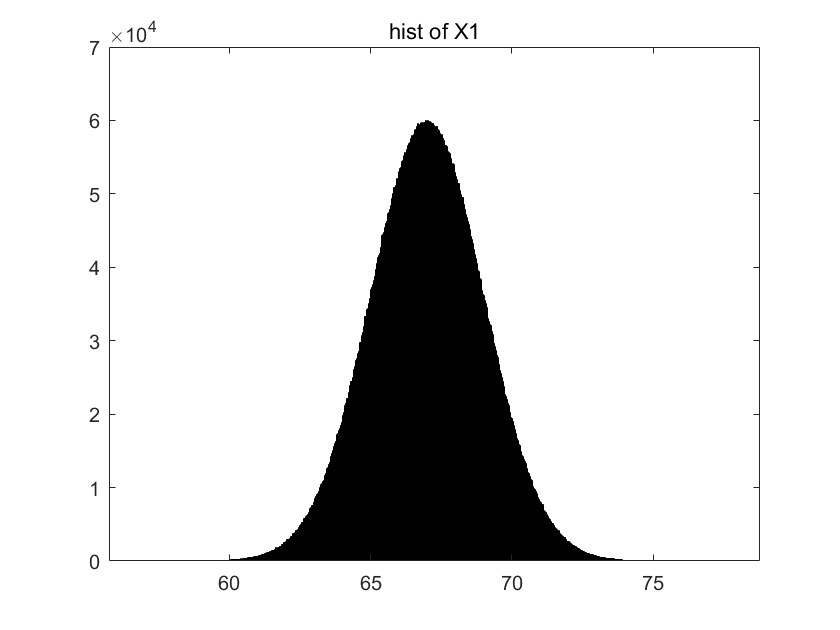


histogram(X1)
title('hist of X1')

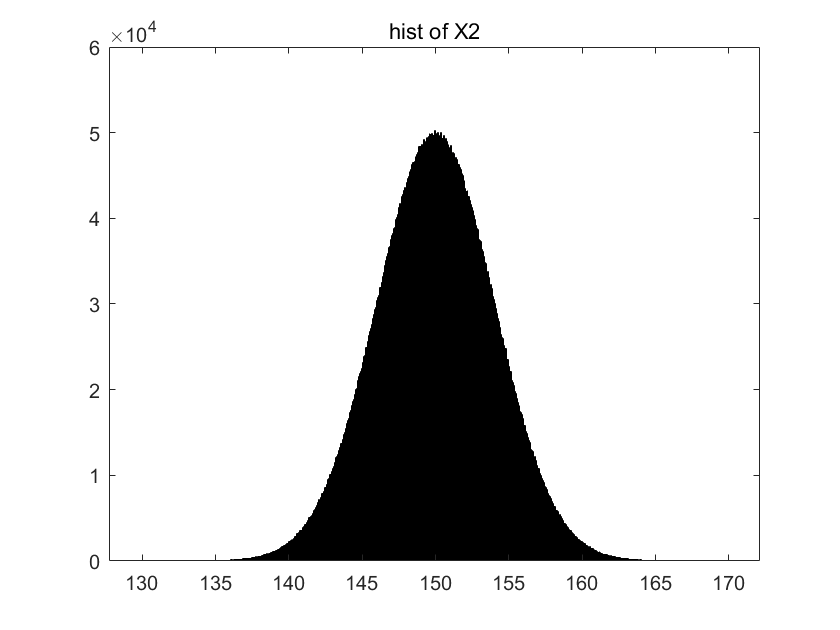

histogram(X2)
title('hist of X2')

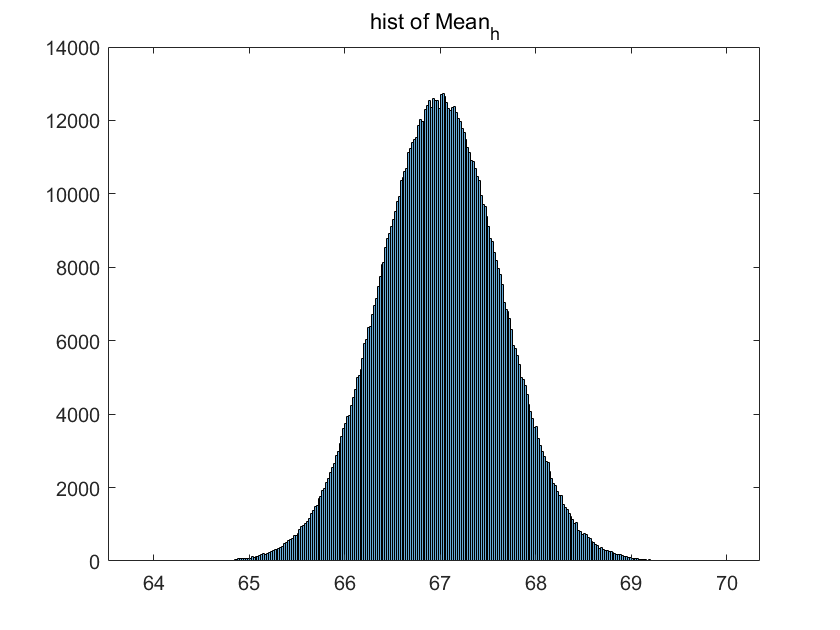

histogram(Mean_Xw_h)
title('hist of Mean_h')

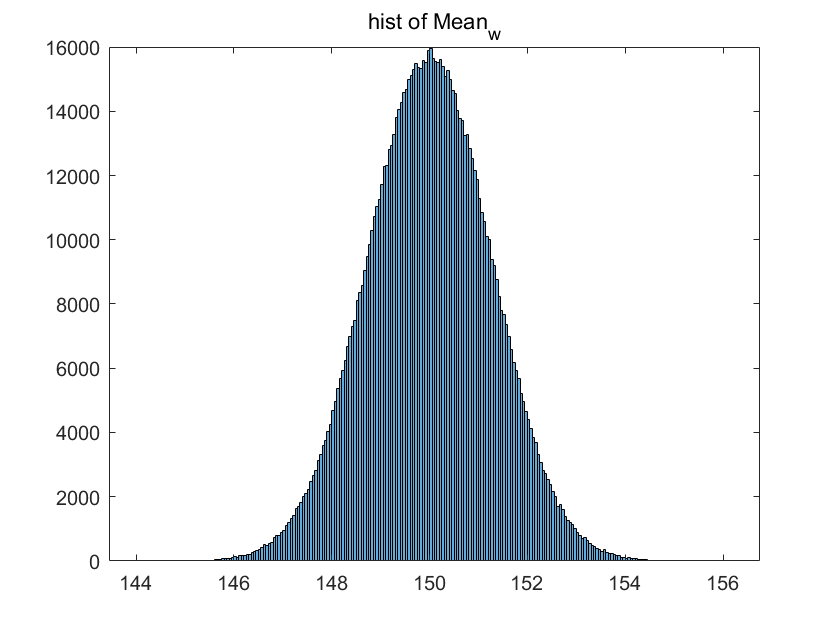

histogram(Mean_Xw_w)
title('hist of Mean_w')

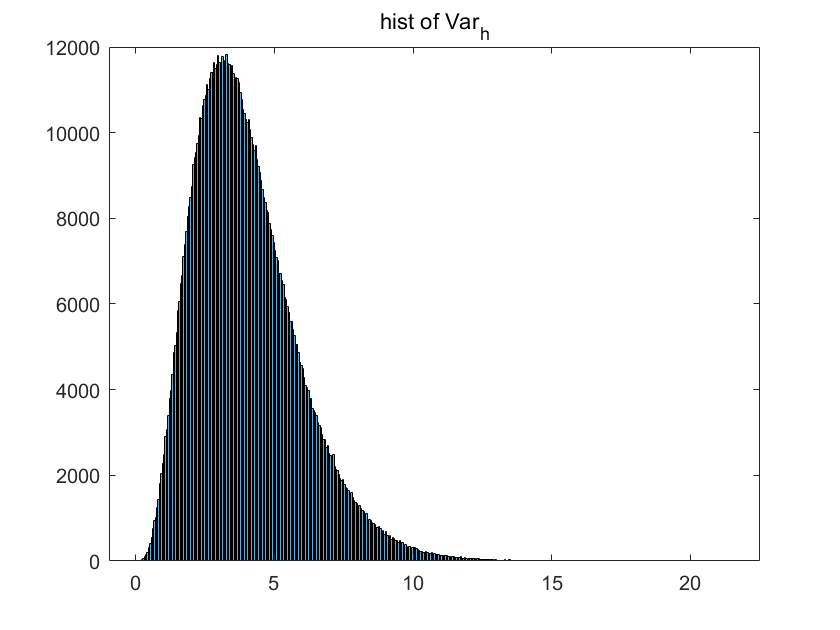

histogram(Var_h)
title('hist of Var_h')

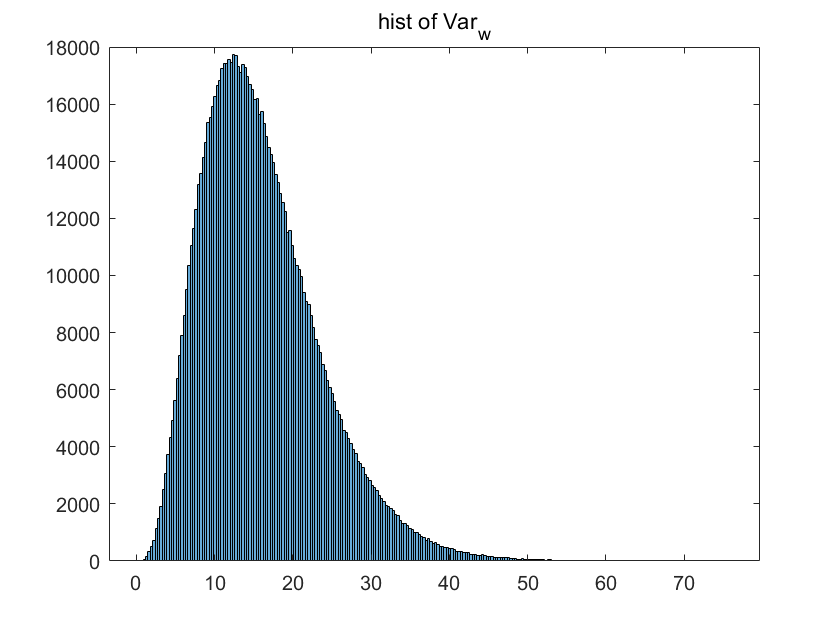

histogram(Var_w)
title('hist of Var_w')

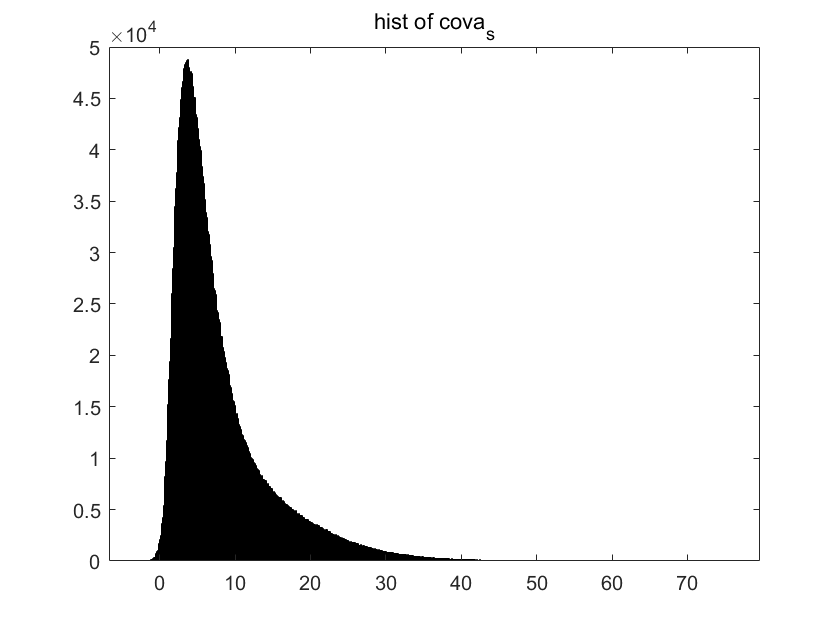

histogram(cova_s)
title('hist of cova_s')